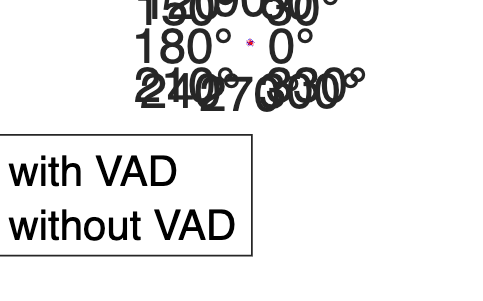

[audio, fs] = audioread('/Users/macos/Documents/MATLAB/Simulation_capstone/dataset/meetingroom10/speaking behind.WAV');  
assert(size(audio, 2) == 4, 'Expected 4-channel WAV file');

c = 343;             % Speed of sound (m/s)
d = 0.06;            % Distance between mics (meters)
N = 4096;            % Frame size (samples)
hop = N / 2;         % 50% overlap
f_low = 300;         % VAD frequency threshold
f_high = 3400;        % Upper frequency for VAD
vad_energy_thresh = 1e-6;
vad_zcr_thresh = 0.08;

mic_pos = [0 0; d 0; d d; 0 d];  % [x y] for each mic
angles = 0:1:359;                % Directions to scan
powers_vad = zeros(size(angles));  % Beamforming with VAD
powers_no_vad = zeros(size(angles));  % Beamforming without VAD

num_frames = floor((size(audio, 1) - N) / hop);
for fi = 1:num_frames
    idx = (fi - 1) * hop + (1:N);
    frame = audio(idx, :) .* hann(N);  % Windowing
    
    x = frame(:, 1);
    
    energy = sum(x.^2) / N;
    zcr = sum(abs(diff(sign(x)))) / (2 * N);
    vad_pass = (energy >= vad_energy_thresh && zcr >= vad_zcr_thresh);

    X = fft(x .* hann(N));
    f_axis = (0:N-1) * fs / N;
    mag = abs(X);
    [~, peak_bin] = max(mag(2:floor(N/2)));  % Ignore DC
    peak_freq = f_axis(peak_bin + 1);
    if peak_freq < f_low || peak_freq > f_high
        continue;  
    end

    %% Phase-Shift Beamforming 
    X_all = fft(frame, N);  % FFT [N x 4]
    bins = round(f_low/fs*N) : round(f_high/fs*N);

    for ai = 1:length(angles)
        theta = deg2rad(angles(ai));
        direction = [cos(theta), sin(theta)];
        delays = mic_pos * direction' / c;

        energy_bf = 0;
        for b = bins
            f_b = f_axis(b);
            X_f = X_all(b, :).';  % [4x1]
            phase_shift = exp(-1j * 2 * pi * f_b * delays);  % [4x1]
            y = sum(X_f .* phase_shift);
            energy_bf = energy_bf + abs(y)^2;
        end

        if vad_pass
            powers_vad(ai) = powers_vad(ai) + energy_bf;
        end
        powers_no_vad(ai) = powers_no_vad(ai) + energy_bf;
    end
end

powers_vad = powers_vad / max(powers_vad);
powers_no_vad = powers_no_vad / max(powers_no_vad);

figure('Units', 'normalized', 'Position', [0.2, 0.2, 0.6, 0.6]);  % Larger figure window
polarplot(deg2rad(angles), powers_vad, 'b', 'LineWidth', 2);
hold on;
polarplot(deg2rad(angles), powers_no_vad, 'r', 'LineWidth', 2);

ax = gca;
ax.FontSize = 14; 

legend('Beamforming with VAD', 'Beamforming without VAD', ...
       'FontSize', 12, 'Location', 'southoutside');

title('Beamforming Comparison: With VAD vs. Without VAD', 'FontSize', 16);



[max_val_vad, idx_vad] = max(powers_vad);
[max_val_no_vad, idx_no_vad] = max(powers_no_vad);
fprintf('Maximum angle with VAD: %.1f° (energy = %.2f)\n', angles(idx_vad), max_val_vad);

Maximum angle with VAD: 270.0° (energy = 1.00)


fprintf('Maximum angle without VAD: %.1f° (energy = %.2f)\n', angles(idx_no_vad), max_val_no_vad);

Maximum angle without VAD: 264.0° (energy = 1.00)
